## Signal Generation

fs = 400;
dt = 0.1;
aquisition_time = 10*dt; % guess
nr_samples = round(fs*aquisition_time);
aquisition_time = nr_samples./fs; % actual
t = linspace(0,aquisition_time,nr_samples);


wave_type = "Triangle";
wave_f = 25;
wave_vpp = 5;
wave_amp = wave_vpp/2;

if wave_type == "Sinusoidal"
    y_orig = sin(wave_f.*2.*pi.*t);
elseif wave_type == "Square"
    y_orig = wavesquare(wave_f,t);
elseif wave_type == "Triangle"
    y_orig = wavetriangle(wave_f,t);
end

wave_noise_max_amp = 0.2;
has_noise = true;

y_source = wave_amp.*y_orig;

## Signal Modification

% Determine aquisition mode
aquisition_type = "Sample";
if aquisition_type == "Average"
    repeats = 10;
else
    repeats = 1;
end

y_samples = zeros(nr_samples,repeats);
for i = 1:repeats
    % Noise
    y = y_source';
    if has_noise && 1 == 1 % removes unreach warning
        y = y + (wave_noise_max_amp*rand(nr_samples,1) - ...
        wave_noise_max_amp/2);  
    end
    y_primary = y';
    % Windowing
    window_type = "Rectangular";
    win_ref = wave_amp.*ones(1,nr_samples);
    if window_type == "Hanning"
        y = hann(nr_samples).*y; 
        win_ref = hann(nr_samples).*wave_amp;
    elseif window_type == "Gaussian"
        y = gausswin(nr_samples).*y;
        win_ref = gausswin(nr_samples).*wave_amp;
    end
    
    y_window = y'; % to plot later
    y_samples(:,i) = y;
end
y_aquisition = sum(y_samples,2)'./repeats;

% Fourier Transform
[Y,f] = fft2NdB(y_aquisition,fs);
if false&& 1 == 1
    flower = 0; fupper = 2500000;
else
    flower = f(1); fupper = f(end);
end

if fupper >= 1000000
    fplot_divisor = 1000000;
    funit = "M";
elseif fupper >= 1000
    fplot_divisor = 1000;
    funit = "k";
else
    fplot_divisor = 1;
    funit = "";
end

% Plot time
fprintf("Samples: %u\n" + ...
    "Aquisition Time: %1.3e seconds\n",...
    nr_samples,aquisition_time);

Samples: 400
Aquisition Time: 1.000e+00 seconds



if t <= 1e-6
    t = t/1e-9;
    t_unit = "n";
elseif t <= 1e-3
    t = t/1e-6;
    t_unit = "\mu";
elseif t <= 1
    t = t/1e-3;
    t_unit = "m"
else
    t_unit = "";
end

t_unit = "m"

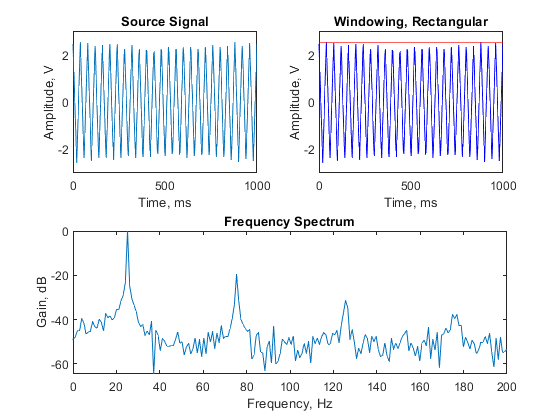



clf
subplot(2,2,1)
plot(t,y_primary)
axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])
title("Source Signal")
xlabel(sprintf("Time, %s%s",t_unit,"s"));
ylabel("Amplitude, V")

subplot(2,2,2)
plot(t,y_window,'b',t,win_ref,'r');
axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])
title("Windowing, " + window_type)
xlabel(sprintf("Time, %s%s",t_unit,"s"));
ylabel("Amplitude, V")
% legend({'Signal','Windowing function'})

if aquisition_type == "Average"
    subplot(2,2,3)
    plot(t,y_aquisition)
    axis([0 t(end) -wave_amp*1.2 wave_amp*1.2])
    title("Average Signal")
    xlabel(sprintf("Time, %s%s",t_unit,"s"));
    ylabel("Amplitude, V")
    subplot(2,2,4)
else
    subplot(2,2,[3,4])
end
plot(f/fplot_divisor,Y);
axis([flower/fplot_divisor fupper/fplot_divisor min(Y) max(Y)])
title("Frequency Spectrum")
xlabel(sprintf("Frequency, %sHz",funit));
ylabel("Gain, dB")